im1=imread('rgb_image_10.png');
im2=imread('rgb_image_17.png');
load depth_10.mat;
dep1=depth_array;
load depth_17.mat;
dep2=depth_array;
load calib_asus.mat;
load pts_10_17.mat
K=Depth_cam.K;
Krgb=RGB_cam.K;


%image 10
xyz=get_xyzasus(dep1(:),[480 640],1:480*640,K,1,0);
imd=get_rgbd(xyz,im1,R_d_to_rgb,T_d_to_rgb,RGB_cam.K);
pc=pointCloud(xyz,"Color",reshape(imd,480*640,3));
pc=pcdownsample(pc,"random",.4);

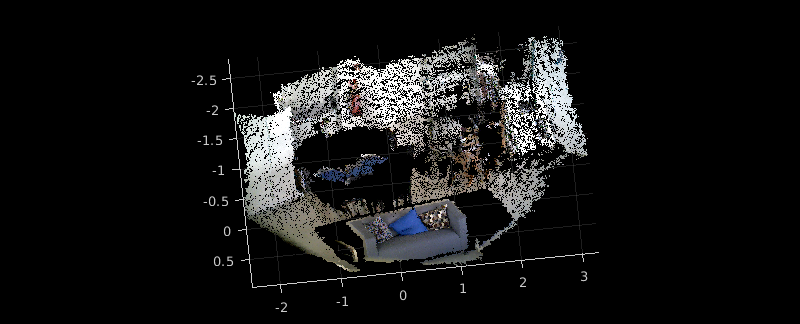

showPointCloud(pc);
view([3.88 -90.00]);

%image 14 - or 17 if you click new points
xyz2=get_xyzasus(dep2(:),[480 640],1:480*640,K,1,0);
imd2=get_rgbd(xyz2,im2,R_d_to_rgb,T_d_to_rgb,RGB_cam.K);
pc2=pointCloud(xyz2,"Color",reshape(imd2,480*640,3));
pc2=pcdownsample(pc2,"random",.4);

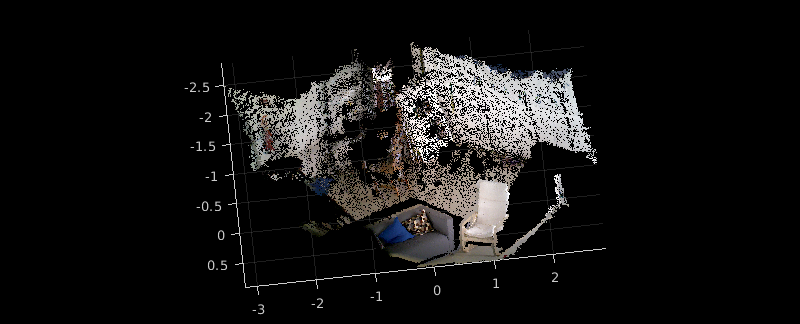

showPointCloud(pc2);
view([3.88 -90.00]);

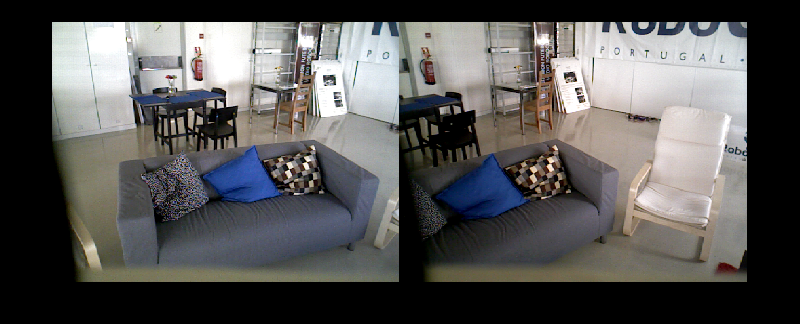

imshow([im1 im2])

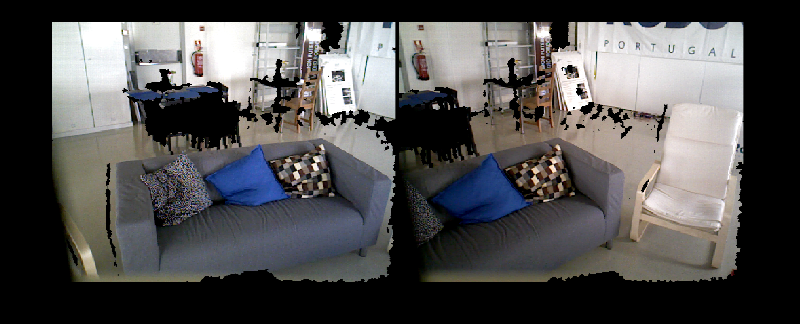

imshow([imd imd2]);

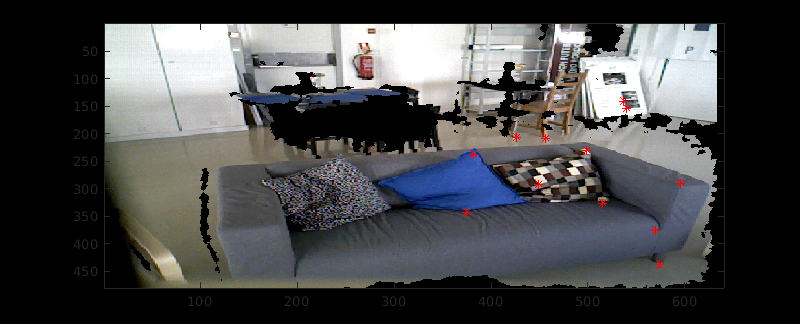

%get corresponding points in two images. 
% Initial set already defined and loaded (pts_10_17.mat) 
% click in a fiew points and get their 3D
%[u v]=ginput(n);
%inds=sub2ind(size(dep1),v,u);
%p=[u v];
%xyz1=xyz(inds1,:);
imagesc(imd);
hold on;plot(p1(:,1),p1(:,2),'*r');

hold off;

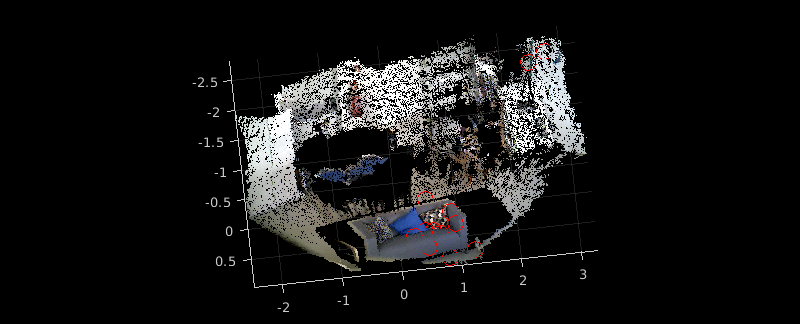

showPointCloud(pc);
hold on
plot3(xyz1(:,1),xyz1(:,2),xyz1(:,3),'or',"MarkerSize",12);
axis equal;hold off;
view([4.14 -90.00])

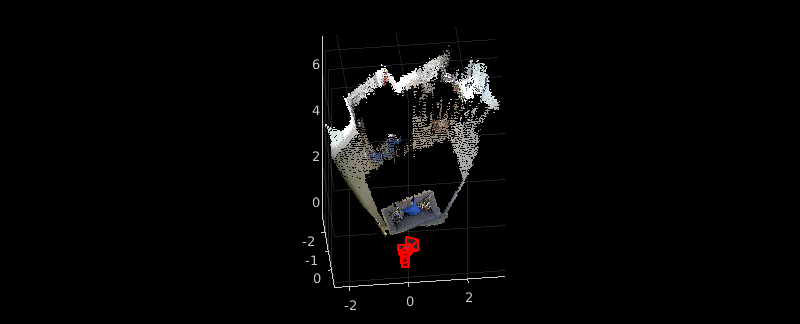

% Use matlab function to compute pose
intrinsics=cameraIntrinsics([Krgb(1,1) Krgb(2,2)],[Krgb(1,3) Krgb(2,3)],[480 640]);
[R,T]=estimateWorldCameraPose(p2,xyz1,intrinsics,'MaxReprojectionError',20);
showPointCloud(pc);hold on;
plotCamera('Size',.23,'Orientation',R,'Location',T);
plotCamera('Size',.23,'Orientation',eye(3),'Location',zeros(3,1));

view([6.20 -39.32])

% m=K*[R -R*T']*[xyz1';ones(1,length(xyz1))];
% xx=m./[ones(3,1)*m(3,:)];

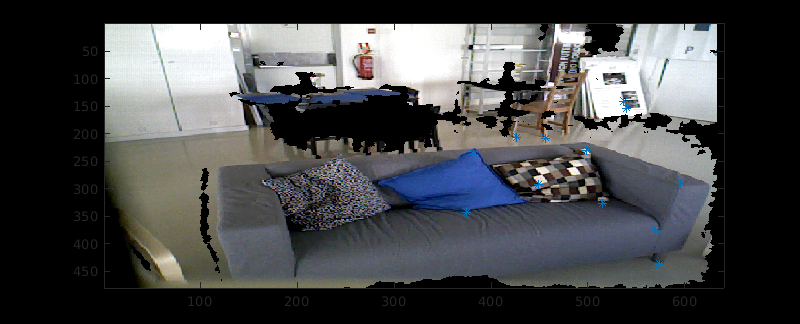

% imagesc(imd);
% hold on;plot(p1(:,1),p1(:,2),'*');
% hold off

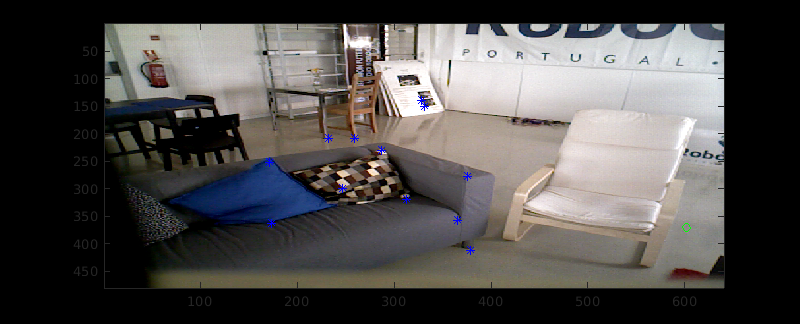

% imagesc(imd2)
% hold on;
% plot(xx(1,:),xx(2,:),'og');
% plot(p2(:,1),p2(:,2),'*b');
% hold off